## **Understanding CIC Compensation Filters**

ALTERA Application Note 455

#### At first, set the CIC filter parameters:

R = 4; %% Decimation factor
M = 1; %% Differential delay
N = 8; %% Number of stages
B = 18; %% Coeffi. Bit-width
Fs = 91.392e6; %% (High) Sampling freq in Hz before decimation
Fc = 4.85e6; %% Pass band edge in Hz
%%%%%%% fir2.m parameters %%%%%%
L = 110; %% Filter order; must be even
Fo = R*Fc/Fs; %% Normalized Cutoff freq; 0<Fo<=0.5/M;
% Fo = 0.5/M; %% use Fo=0.5 if you don't care responses are


#### and buld the CIC filter:

cicdecim = dsp.CICDecimator(...
    'DecimationFactor',R,...
    'NumSections',N);
decimcasc = dsp.FilterCascade(cicdecim,...
    1/gain(cicdecim));


#### then create the FIR filter compensating the CIC filter, using dsp.fir2:

p = 2e3; %% Granularity
s = 0.25/p; %% Step size
fp = [0:s:Fo]; %% Pass band frequency samples
fs = (Fo+s):s:0.5; %% Stop band frequency samples
f = [fp fs]*2; %% Normalized frequency samples; 0<=f<=1
Mp = ones(1,length(fp)); %% Pass band response; Mp(1)=1
Mp(2:end) = abs( M*R*sin(pi*fp(2:end)/R)./sin(pi*M*fp(2:end))).^N;
Mf = [Mp zeros(1,length(fs))];
f(end) = 1;
h = fir2(L,f,Mf); %% Filter length L+1
h = h/max(h); %% Floating point coefficients
hz = round(h*power(2,B-1)-1); %% Fixed point coefficients


#### and build it:

fircomp_gain = dsp.FIRFilter(hz);
fircomp = dsp.FilterCascade(fircomp_gain, 1/sum(hz));


#### Finally create the CIC + FIR filter:

% Create the CIC + FIR filter
cicfir = dsp.FilterCascade(decimcasc, fircomp);


#### Show the three filters:

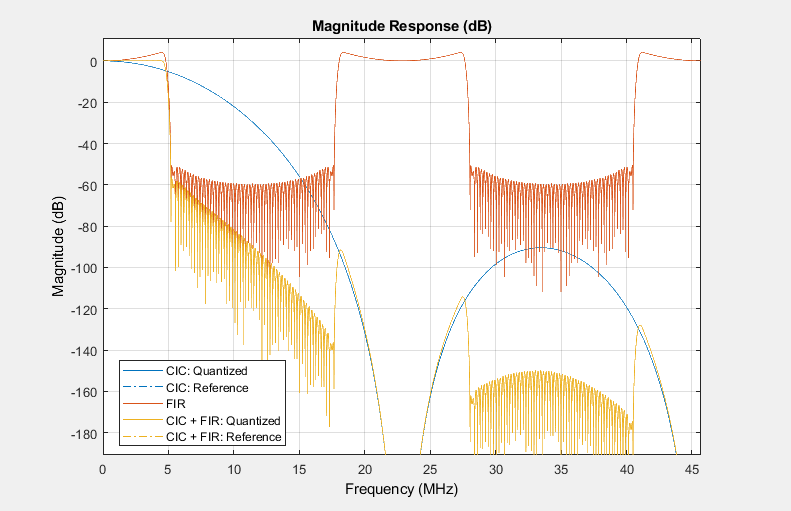

% view the three filters
myfv = fvtool(decimcasc, fircomp, cicfir, 'Fs', [Fs, Fs/R, Fs]);
legend(myfv, "CIC", "FIR", "CIC + FIR");  